# ELEN 142L Lab 5 -- Ayden Dauenhauer and Qiming Xie

## Part 1: Data Generation

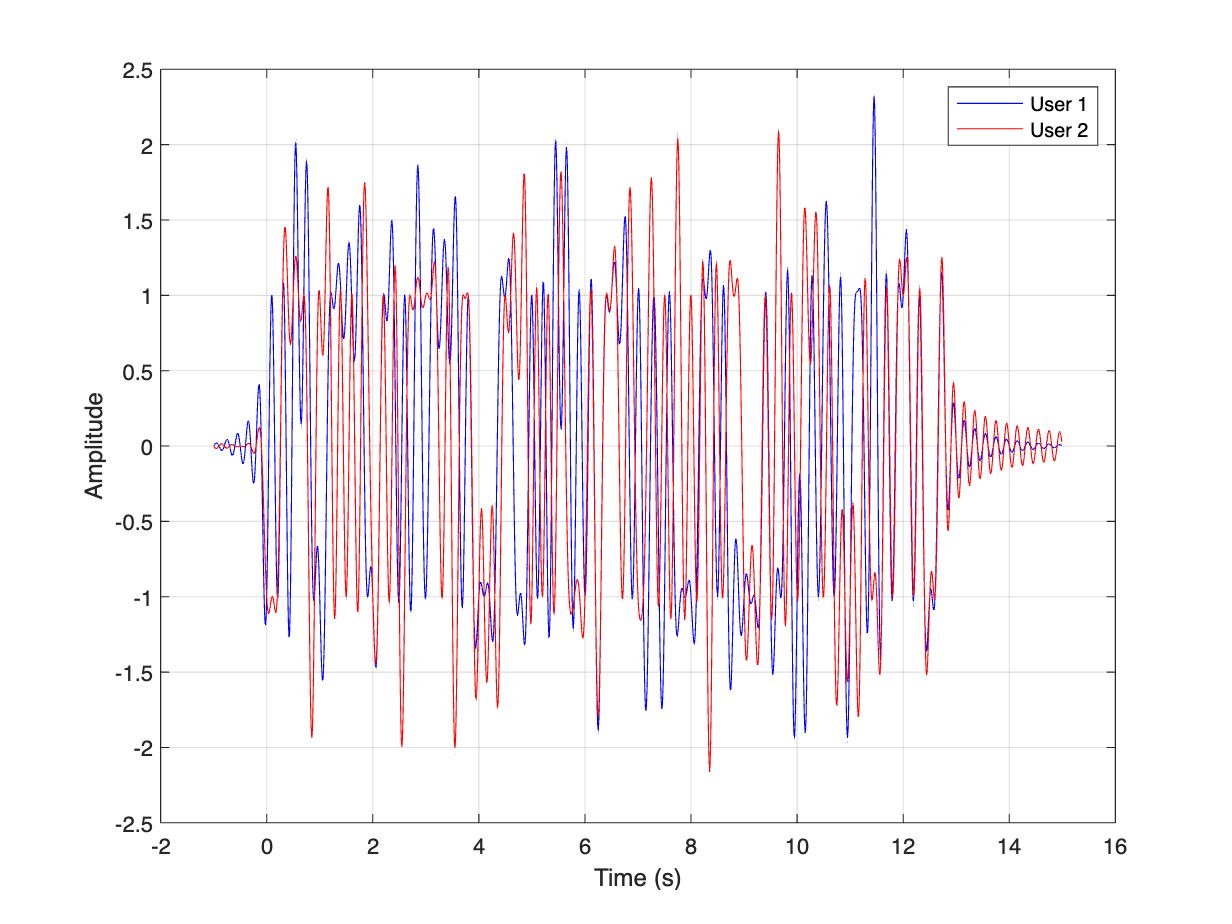

% Step 1
Fs = 100;
T = 1 / Fs;
t = -1:T:14.99;

user1 = zeros(size(t));
user2 = zeros(size(t));

rand1 = 2*round(rand(1,128))-1;
rand2 = 2*round(rand(1,128))-1;

% Step 2
for i = 1:128
    pulse = sinc((t-(i-1)*0.1)/0.1);

    user1 = user1 + rand1(i) * pulse;
    user2 = user2 + rand2(i) * pulse;
end

figure;
plot(t, user1, 'b', 'DisplayName', 'User 1');
hold on;
plot(t, user2, 'r', 'DisplayName', 'User 2');
xlabel('Time (s)');
ylabel('Amplitude');
legend;
grid on;

**Look up the rand() function - what transformation did we apply, and what is the result?**

    rand() generates random numbers between 0 and 1. The transformation maps the random values into random binary values of -1 and 1.

**Plot both signals in one plot. Are the signals visibly different?**

    Yes, the signals are visibly different.

## Part 2: TDMA

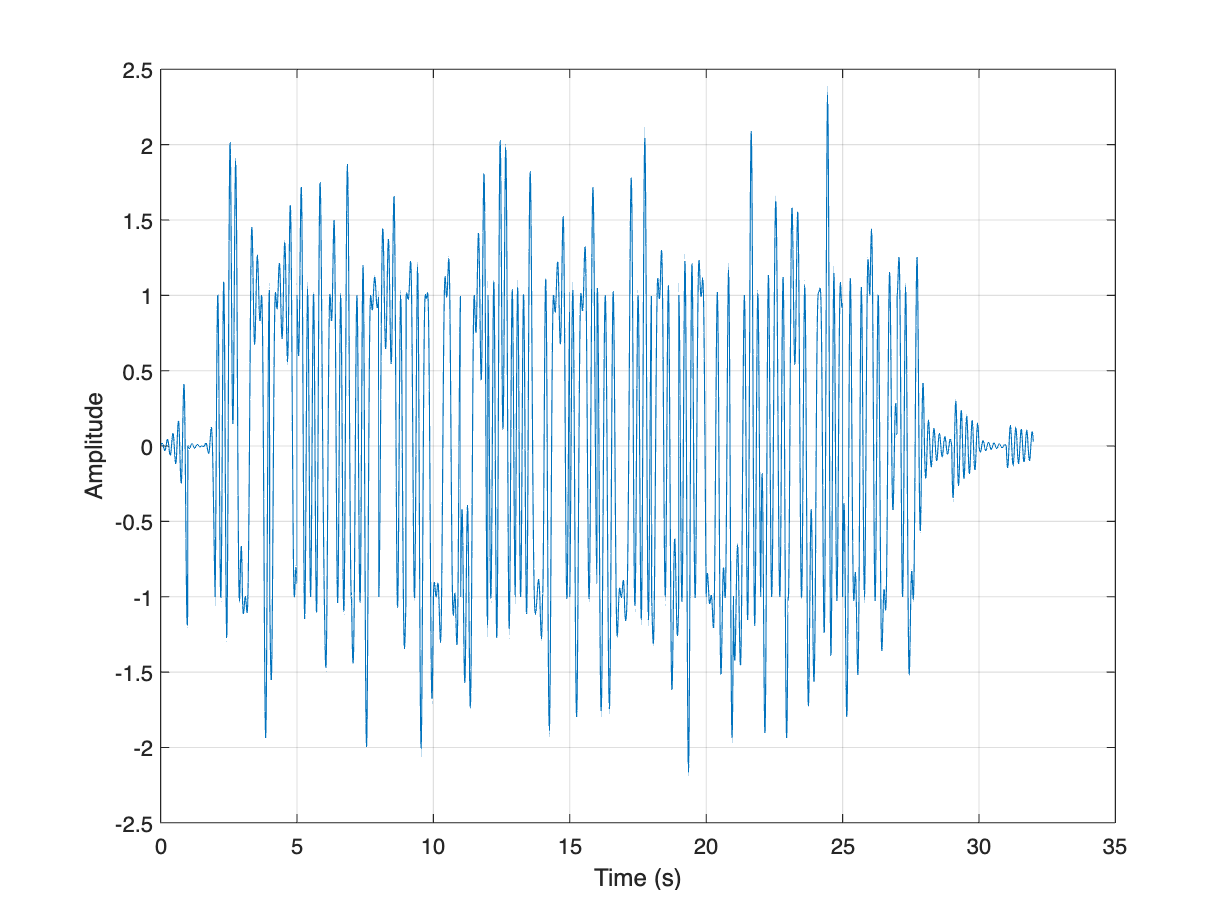

% Step 1
time_div = 0.0100;
sample_div = 1 / time_div;

idx = 1;
for i = 1:sample_div:length(user1)
    end_idx = min(i + sample_div - 1, length(user1));

    xTDMA(idx : idx + (end_idx - i)) = user1(i:end_idx);
    idx = idx + (end_idx - i) + 1;

    xTDMA(idx : idx + (end_idx - i)) = user2(i:end_idx);
    idx = idx + (end_idx - i) + 1;
end

t_TDMA = (0:length(xTDMA)-1) / Fs;

figure;
plot(t_TDMA, xTDMA);
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

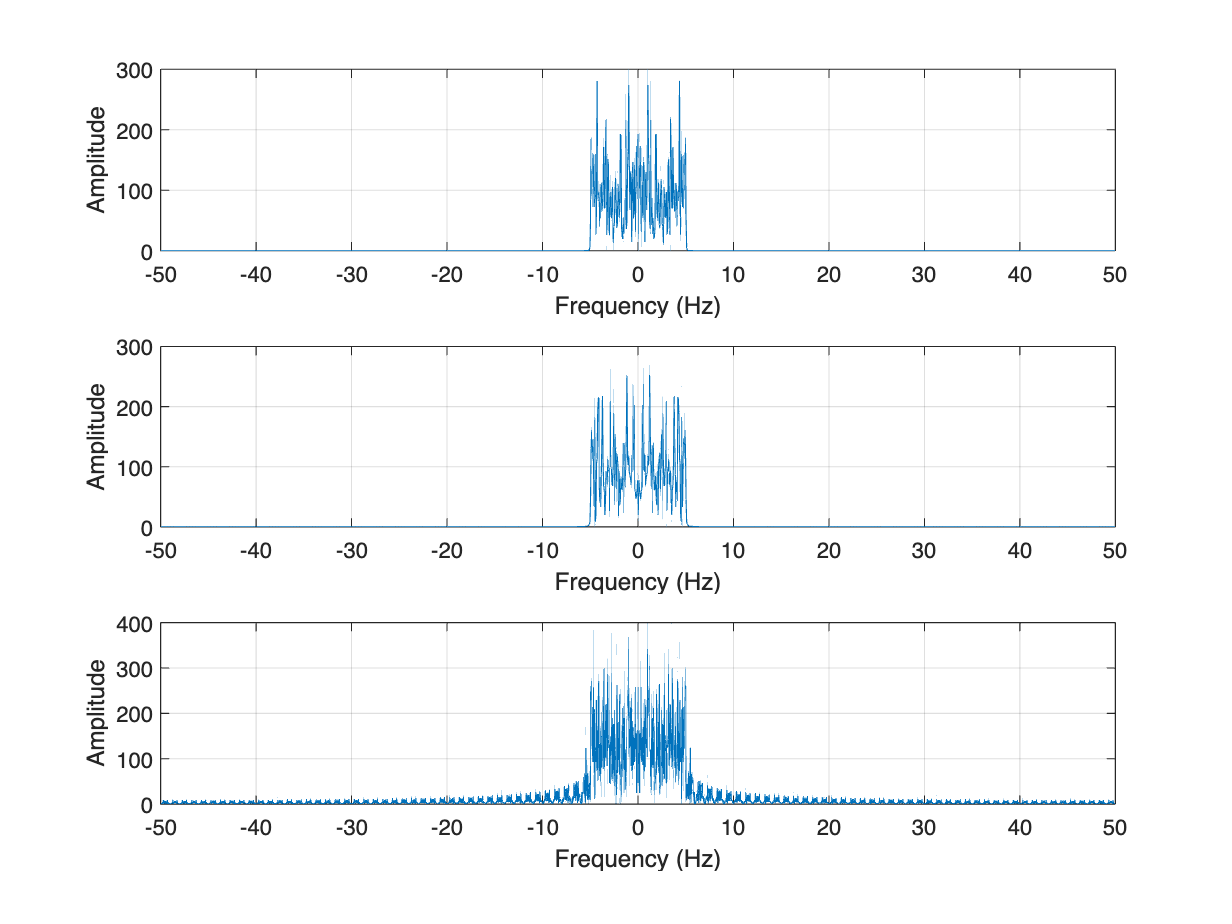

% Step 2
X_user1 = fft(user1);
shift_user1 = fftshift(X_user1);
freqaxis_user = Fs*(linspace(-0.5,0.5,length(t)));

X_user2 = fft(user2);
shift_user2 = fftshift(X_user2);

X_TDMA = fft(xTDMA);
shift_TDMA = fftshift(X_TDMA);
freqaxis_TDMA = Fs*linspace(-0.5,0.5,length(xTDMA));

figure;
subplot(3,1,1);
plot(freqaxis_user, abs(shift_user1));
xlabel('Frequency (Hz)');
ylabel('Amplitude');
grid on;

subplot(3,1,2);
plot(freqaxis_user, abs(shift_user2));
xlabel('Frequency (Hz)');
ylabel('Amplitude');
grid on;

subplot(3,1,3);
plot(freqaxis_TDMA, abs(shift_TDMA));
xlabel('Frequency (Hz)');
ylabel('Amplitude');
grid on;

**What conclusions can you draw from these plots?**

    They have a bandwidth of 10 (from Frequency = -5 to 5). The third plot also has peaks outside of the -5, 5 bound.

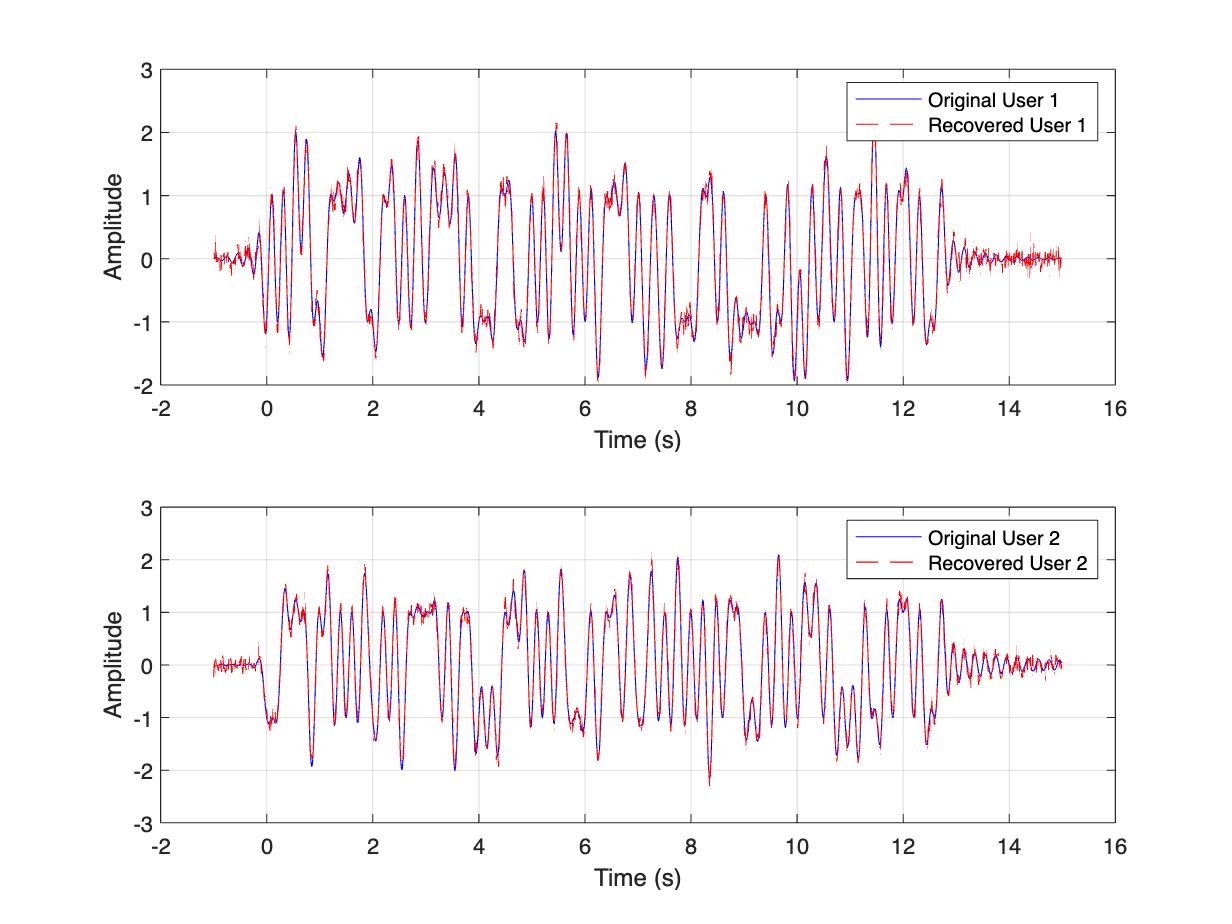

% Step 3
rx_TDMA = xTDMA +.1*randn(size(xTDMA));
rx_user1 = zeros(1, length(t));
rx_user2 = zeros(1, length(t));

idx = 1;
for i = 1:sample_div:length(user1)
    end_idx = min(i + sample_div - 1, length(user1));

    rx_user1(i:end_idx) = rx_TDMA(idx : idx + (end_idx - i));
    idx = idx + (end_idx - i) + 1;

    rx_user2(i:end_idx) = rx_TDMA(idx : idx + (end_idx - i));
    idx = idx + (end_idx - i) + 1;
end

figure;
subplot(2,1,1);
plot(t, user1, 'b', t, rx_user1, 'r--');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Original User 1', 'Recovered User 1');
grid on;

subplot(2,1,2);
plot(t, user2, 'b', t, rx_user2, 'r--');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Original User 2', 'Recovered User 2');
grid on;

**Can you tell that the received signal is the same?**

    Yes, it is very easy to see that the signals are the same because of the overlapping colors.

## Part 3: FDMA

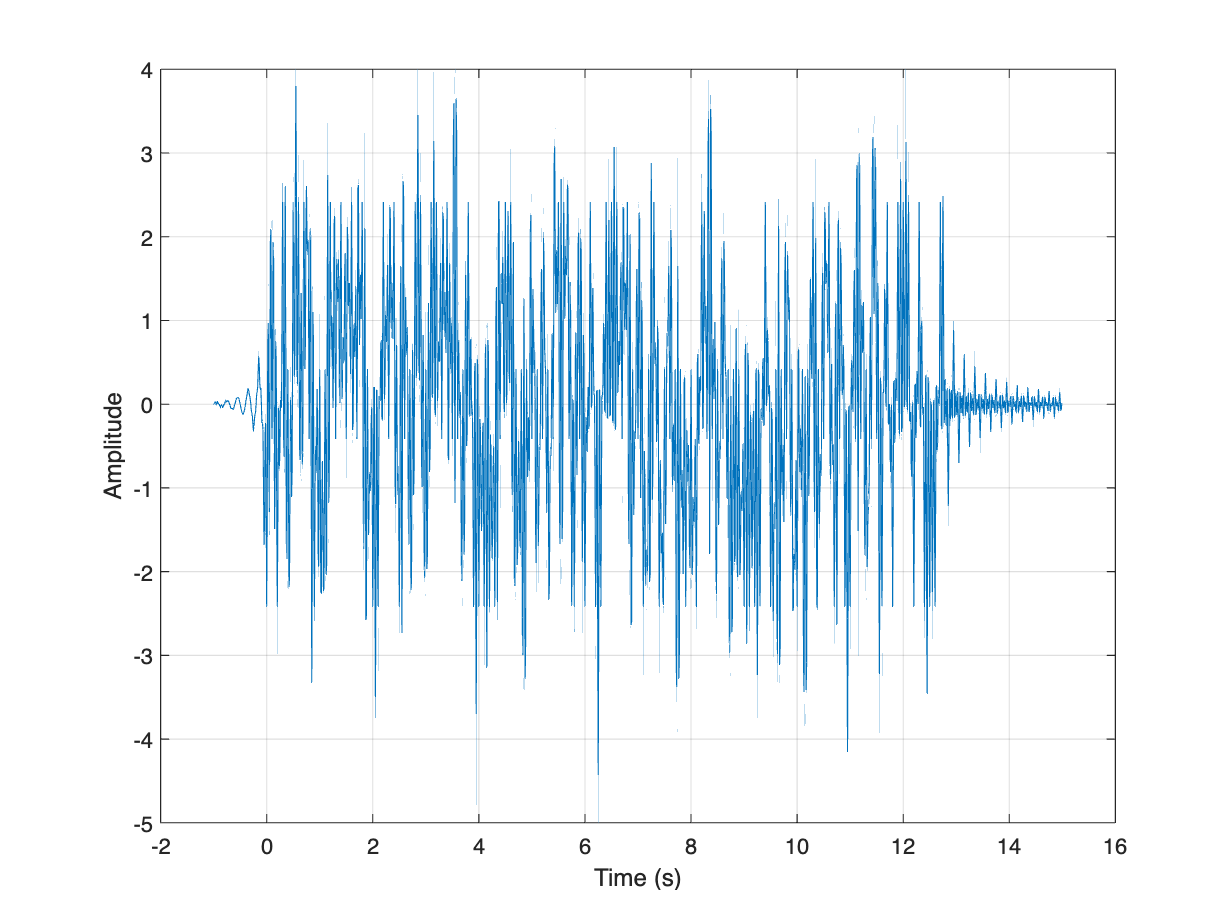

% Step 1
freq_spacing = 20;
modulator = cos(2*pi*freq_spacing*t);
xFDMA = user1 + sqrt(2)*user2.*modulator;

figure;
plot(t, xFDMA);
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

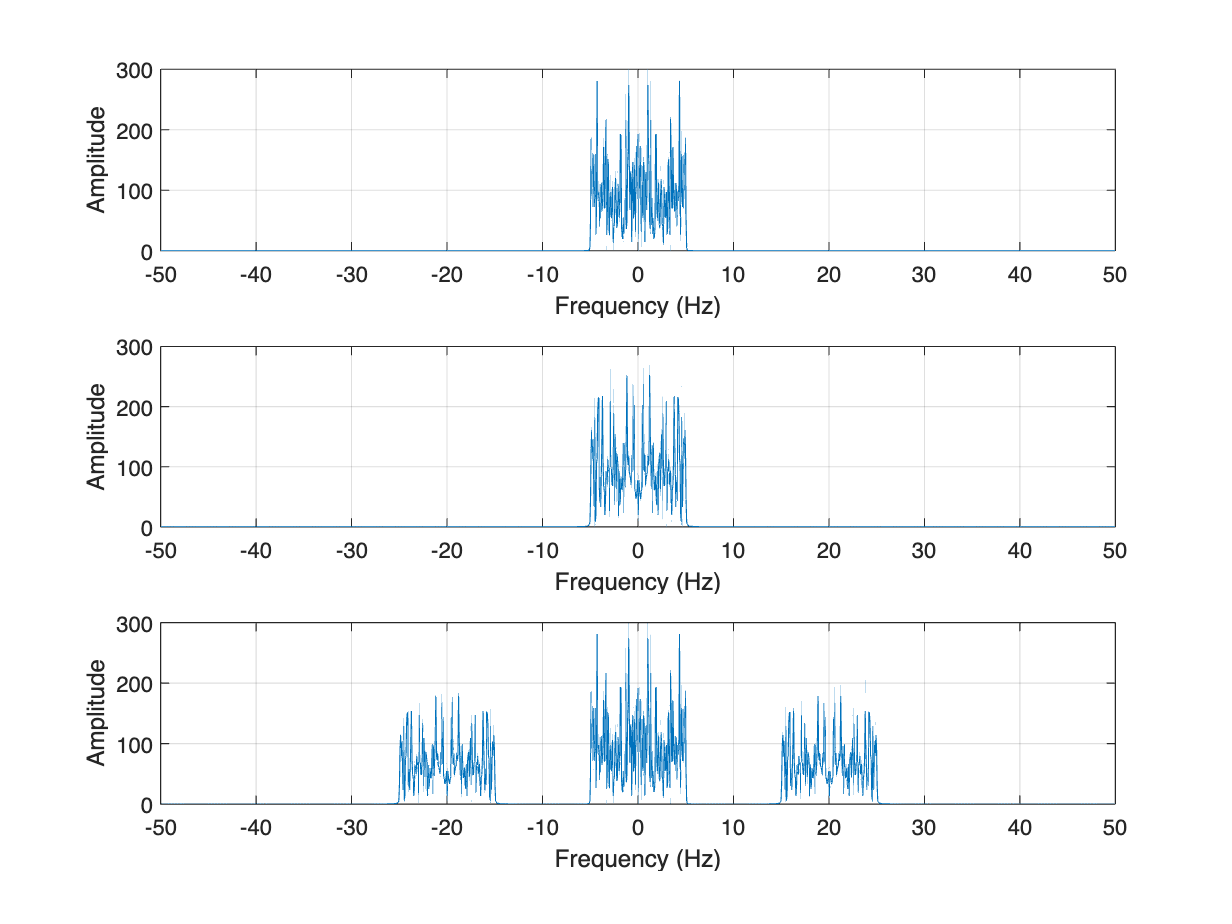

% Step 2
X_user1 = fft(user1);
shift_user1 = fftshift(X_user1);
freqaxis_user = Fs*(linspace(-0.5,0.5,length(t)));

X_user2 = fft(user2);
shift_user2 = fftshift(X_user2);

X_FDMA = fft(xFDMA);
shift_FDMA = fftshift(X_FDMA);
freqaxis_FDMA = Fs*linspace(-0.5,0.5,length(xFDMA));

figure;
subplot(3,1,1);
plot(freqaxis_user, abs(shift_user1));
xlabel('Frequency (Hz)');
ylabel('Amplitude');
grid on;

subplot(3,1,2);
plot(freqaxis_user, abs(shift_user2));
xlabel('Frequency (Hz)');
ylabel('Amplitude');
grid on;

subplot(3,1,3);
plot(freqaxis_FDMA, abs(shift_FDMA));
xlabel('Frequency (Hz)');
ylabel('Amplitude');
grid on;

**Remembering the FFT recipe from the last section, plot the FFT’s of both input signals and the FDMA signal on the same plot. Describe how it looks - is it what you expected?**

    It is what we expected because there is a bandwidth of 10 on the first 2 plots and the third plot has multiple bandwidths of 10 (-25, -15) and (-5, 5) and (15, 25) for the multiple users.

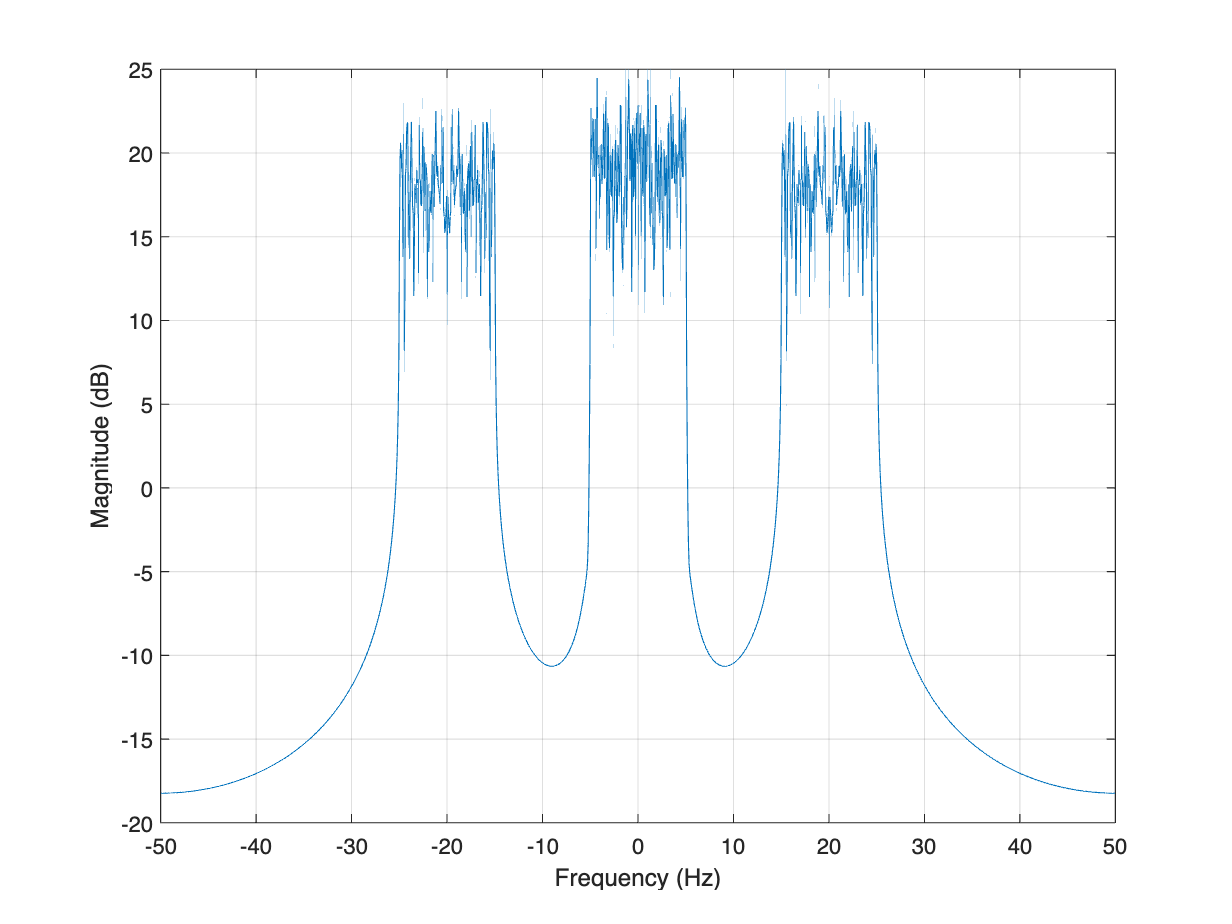

figure;
plot(freqaxis_FDMA, 10*log10(abs(shift_FDMA)));
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;

**How did that change the plot?**

    The plot is now in DB form and shows the magntitude in DB. The bandwidth sections are still clearly visible.

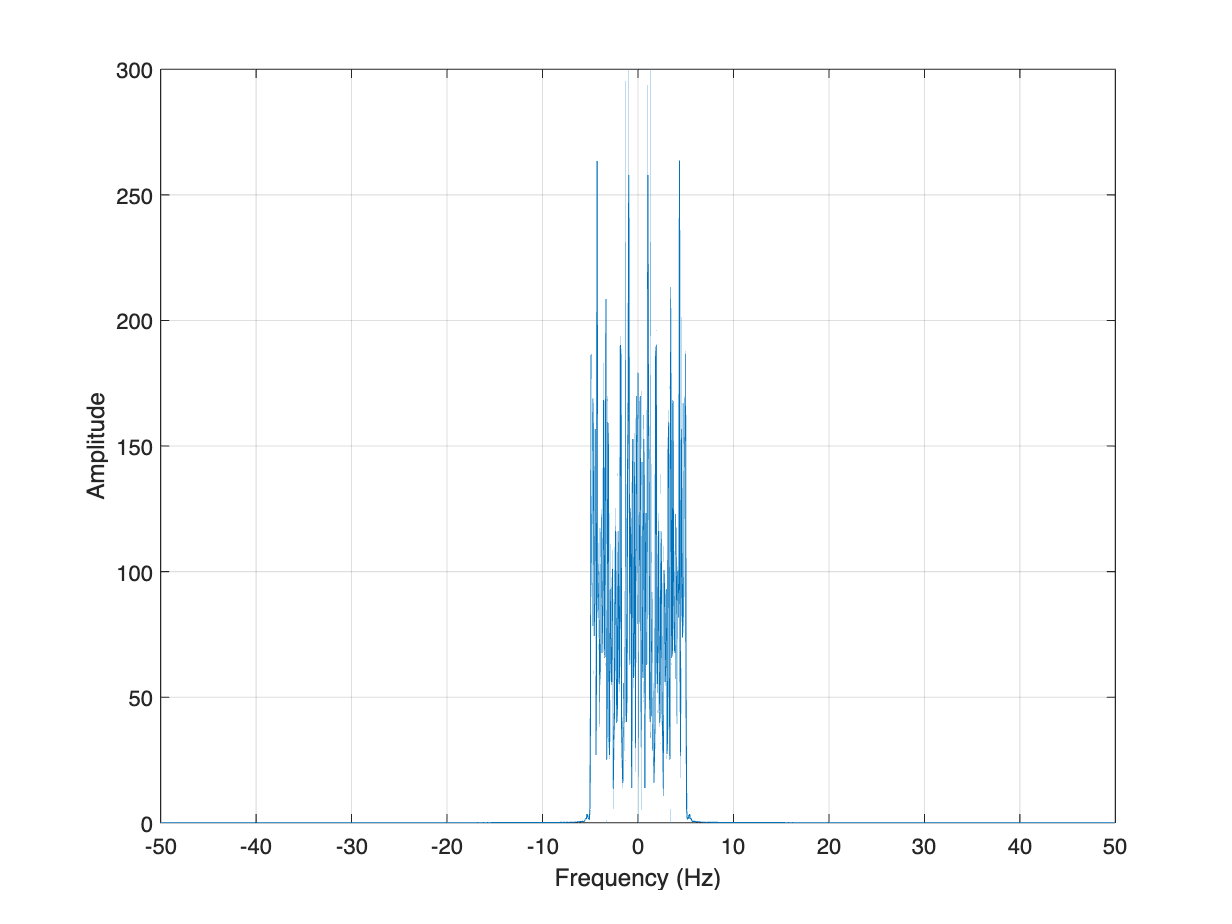

% Step 3
%save('fdma_lowpass.mat','fdma_lowpass');
load('fdma_lowpass.mat');

% Step 4
received = xFDMA +.1*randn(size(xFDMA));
lowpassed = filter(fdma_lowpass, 1, received);

X_low = fft(lowpassed);
shift_lowpassed = fftshift(X_low);
freqaxis_lowpassed = Fs*(linspace(-0.5,0.5,length(lowpassed)));

figure;
plot(freqaxis_lowpassed, abs(shift_lowpassed));
xlabel('Frequency (Hz)');
ylabel('Amplitude');
grid on;

**Plot this new signal in frequency. Does it look like you wanted your low pass filtered signal to look?**

     Yes, this looks good because there is high amplitude at low frequencies so it is a lowpass.

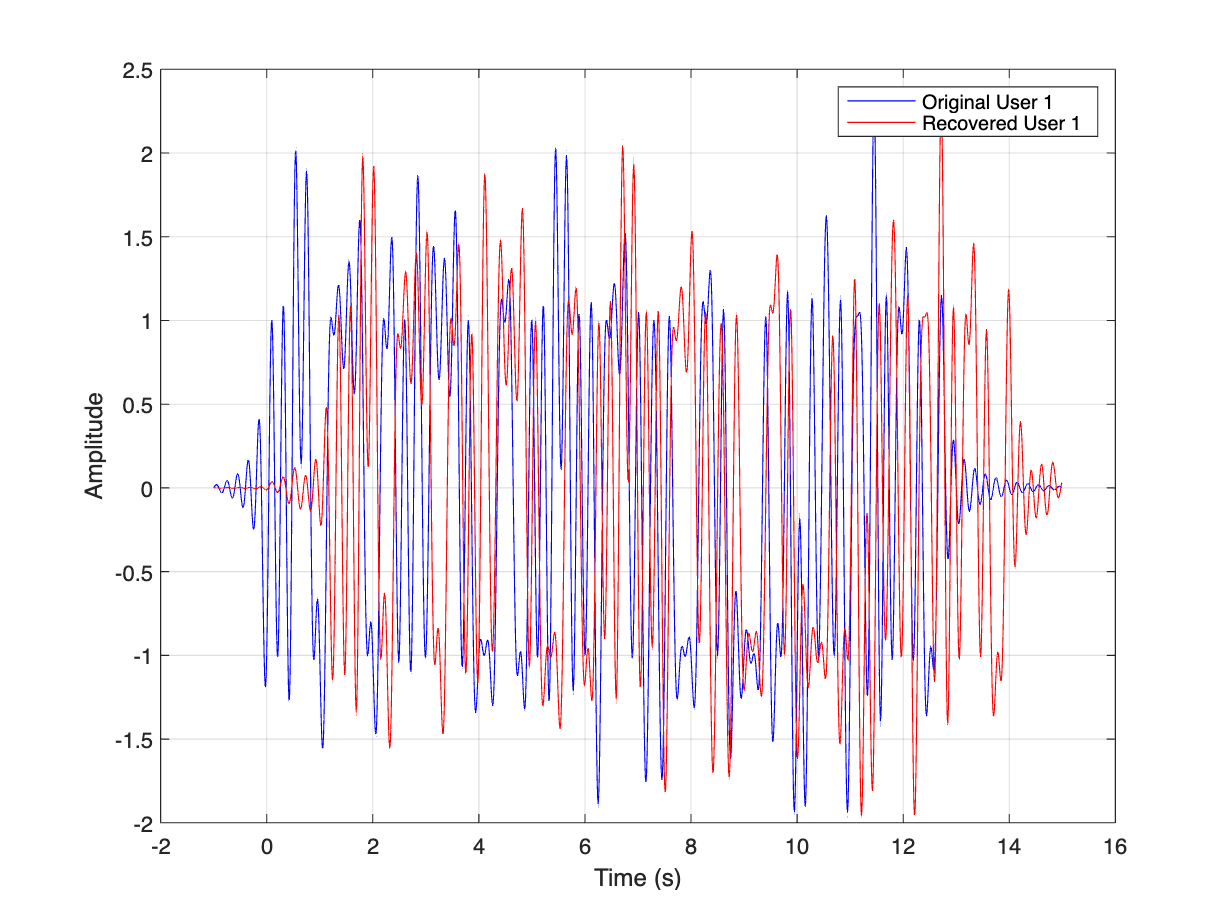

figure;
plot(t, user1, 'b', 'DisplayName', 'Original User 1');
hold on;
plot(t, lowpassed, 'r', 'DisplayName', 'Recovered User 1');
xlabel('Time (s)');
ylabel('Amplitude');
legend;
grid on;

**How similar are the two signals?**

    The two signals are almost identical, the recovered signal is just delayed.

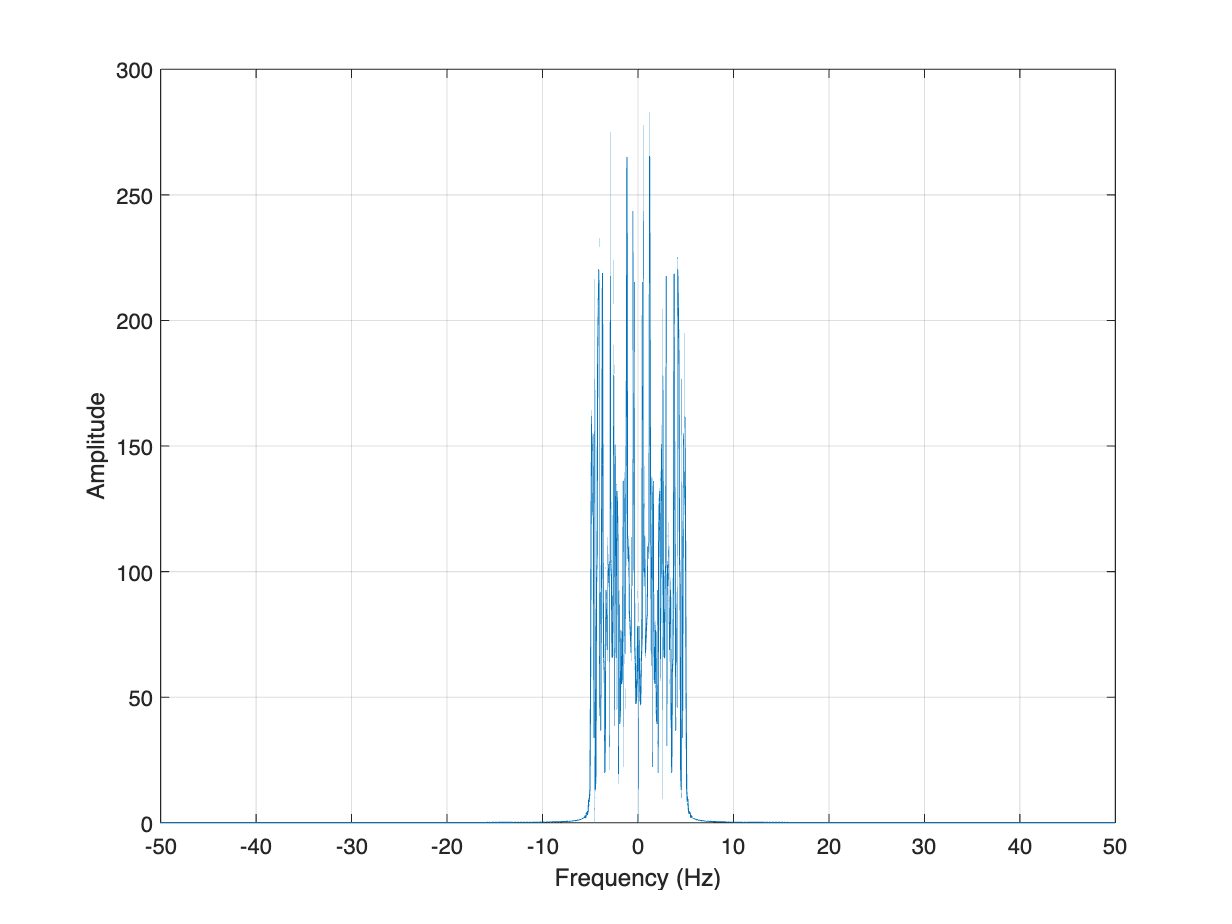

% Step 5
demodulated = sqrt(2) * received .* modulator;
recovered_user2 = filter(fdma_lowpass, 1, demodulated);

X_rec2 = fft(recovered_user2);
shift_rec2 = fftshift(X_rec2);
freqaxis_rec2 = Fs*(linspace(-0.5,0.5,length(recovered_user2)));

figure;
plot(freqaxis_rec2, abs(shift_rec2));
xlabel('Frequency (Hz)');
ylabel('Amplitude');
grid on;

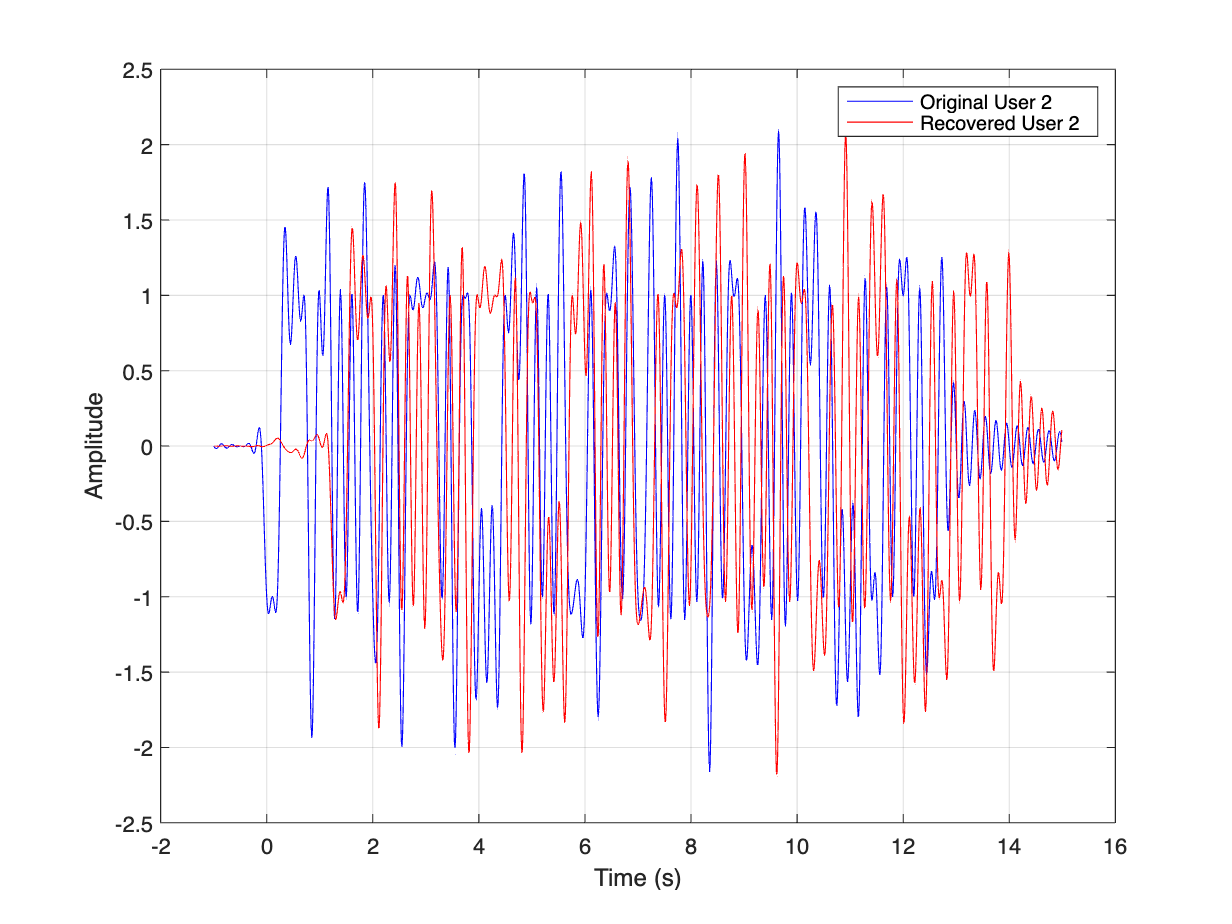

figure;
plot(t, user2, 'b', 'DisplayName', 'Original User 2');
hold on;
plot(t, recovered_user2, 'r', 'DisplayName', 'Recovered User 2');
xlabel('Time (s)');
ylabel('Amplitude');
legend;
grid on;

**What did you observe from the experiments?**

    TDMA allowed two users to share the same communication channel. FDMA used modulation to shift one signal in frequency. The FFT plots showed how each technique distributed signal energy across time or frequency, illustrating the bandwidth and separation clearly.

**If you could expand this experiment how would you do it?**

    We could increase the number of users to test how it works with a large amount of users.

**How does the experiment relate to the course topic?**

    It applies concepts we learnt in class such as: modulation, demodulation, filtering, and signal multiplexing.

**What did you learn from the experiment?**

    We learnt TDMA by interleaving samples and FDMA by frequency modulation and filtering.